# Homework 2

requiements:

- the phase margin must be at least 65$\degree$ and

- the settling time within a $\pm 2%$ band must be less than 2 seconds, in the case of a step input,

        while

- the steady state error of the system in the case of a unit ramp input should not exceed 0.5.

 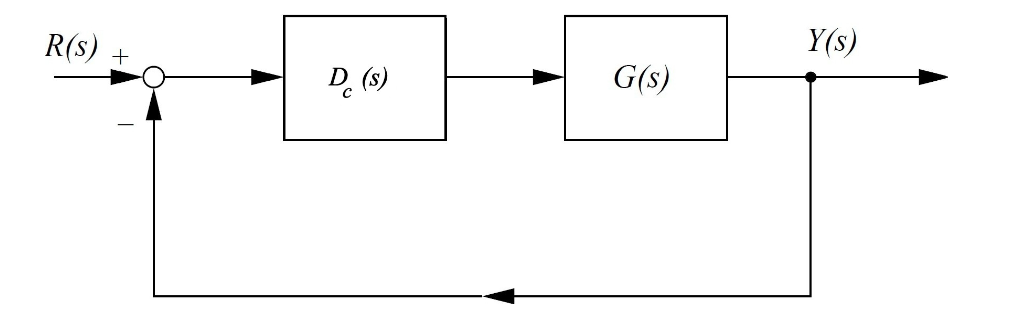

clearvars, clc, close all

The plant is: $G\left(s\right)=\frac{4}{s\left(s+10\right)\left(s+2\right)}$

Gpoles = [0 -10 -2]

Gpoles =      0   -10    -2


G = zpk([],Gpoles,4.0)


G =
 
        4
  --------------
  s (s+10) (s+2)
 
Continuous-time zero/pole/gain model.


To start off this design, the steady state error is calculated in terms of the ramp error constant $K_v$ and thus a required value of is established:


$$e_{\textrm{ss}} =\frac{A}{K_v }\le 0\ldotp 5$$



$$K_v \ge 2$$


It is important to realize that this value represents the required $K_v$ .

The actual $K_v$ will depend on the gain chosen by the designer. If for instance the designer chooses to start his design by selecting $D_c \left(s\right)=1$and he/she then calculates the actual $K_v$. Here $K_v =\frac{4}{20}=0\ldotp 2$, is small by a factor of 10. So we can put a gain $K_1 =10$ in series with the plant.

K1 = 10

K1 = 10

% kvcheck: NJ Theron's function to calculate
% velocity error constant
T = feedback(K1*G,1)


T =
 
                 40
  --------------------------------
  (s+10.45) (s^2 + 1.547s + 3.827)
 
Continuous-time zero/pole/gain model.


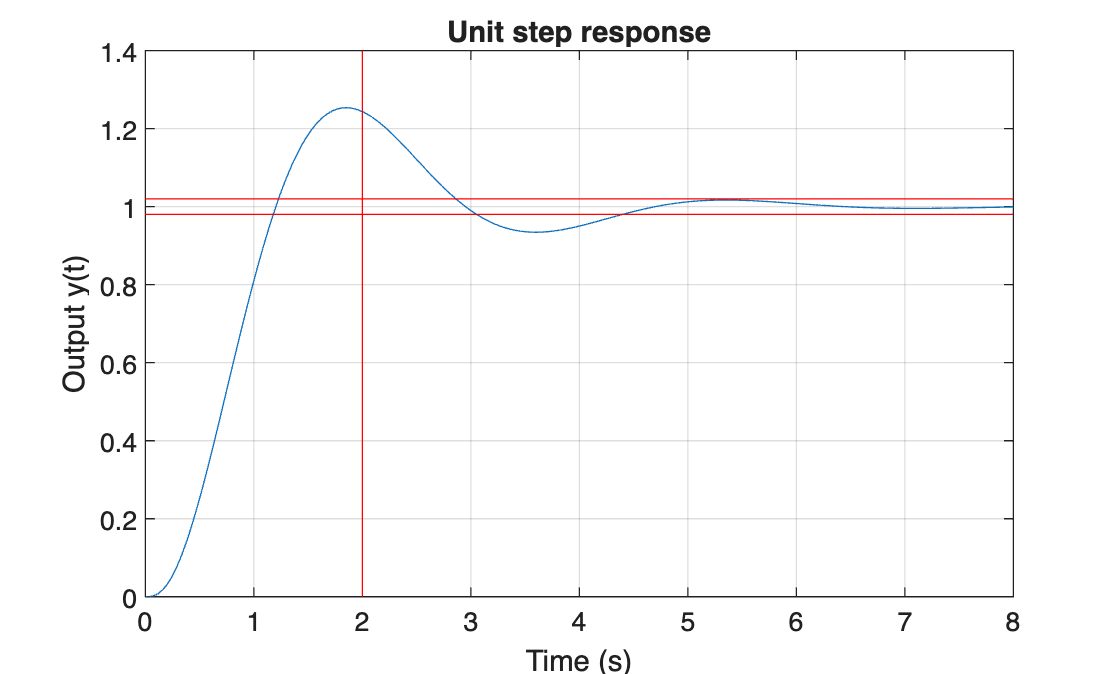

tt = linspace(0.0,8.0,200);
y = step(T,tt);
figure(1)
plot(tt,y)
hold on
%plot([tt(1), tt(end)],[1.05, 1.05],'g')
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([2,2],[0,1.4],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')

Now we plot the Bode diagram of the uncompensated system.

figure(2)
omega = logspace(0,2,400);
[mag1,phase1] = bode(K1*G,omega);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);
subplot(2,1,1),semilogx(omega,20*log10(mag1))
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
hold on
grid on
title('Plant (open loop) transfer function bode diagram')
subplot(2,1,2),semilogx(omega,phase1)
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
grid on
[Gm,Pm,omegcp,omegcg] = margin(K1*G);
dBGm = 20*log10(Gm);
disp(['System phase margin (degrees): ',num2str(Pm)])

System phase margin (degrees): 43.2099


disp(['System cross over angular frequency (rad/s): ',num2str(omegcg)])

System cross over angular frequency (rad/s): 1.5587


disp(['System gain margin (dB): ',num2str(dBGm)])

System gain margin (dB): 15.563


disp(['System Phase Crossover Frequency (rad/s):',num2str(omegcp)])

System Phase Crossover Frequency (rad/s):4.4721


We therefore need to turn to step 3: Allowing for a small amount of safety, determine the necessary additional phase lead $\phi_{\max }$.

Since the phase margin of the gain adjusted uncompensated system is about $43\degree$ degrees but we need $65\degree$, we would like to add about 22 degrees of additional phase to the phase diagram at the angular frequency where the compensated loop transfer function logarithmic gain curve will drop through 0 dB. It is suggested that we add something as a measure of safety, so, I decided to start off my design iterations with $\phi_{\max } =32\degree$.

From Franklin Eq.6.40


$$\alpha =\frac{1-\sin \;\phi_{\max } }{1+\sin \;\phi_{\max } }$$


phi = deg2rad(37)

phi = 0.6458

alpha = (1-sin(phi))/(1+sin(phi))

alpha = 0.2486

disp("To have phi_max = 37 degrees, we need alpha to be "+num2str(alpha))

To have phi_max = 37 degrees, we need alpha to be 0.24858


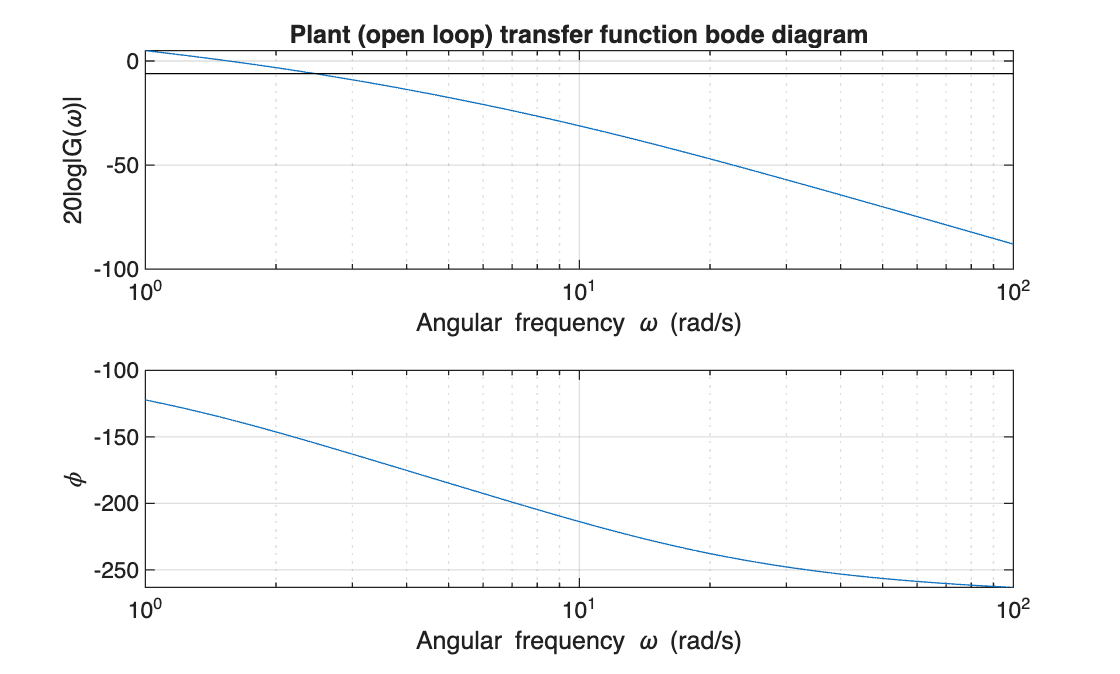

bb = 10*log10(alpha);
figure(2)
subplot(2,1,1),semilogx([omega(1), omega(end)],[bb, bb],'k')

From Bode diagram, the $\omega_{\max } \;$is read off by 2.46 rad/s.


$$T_D =\frac{1}{\omega_{\max } \sqrt{\alpha }}$$


and Then the compensator is calculated as: $D_C =\frac{T_D s+1}{\alpha \;T_D s+1}$

%omegam = 2.46 % read off the Bode diagram in figure 2, for phi_max = 37 degrees
% below: read off the Bode diagram in figure 2, for phi_max = 37, but then
% slightly higher.
omegam = 3.6

omegam = 3.6000

%omegam = ginput(1);
%omegam = omegam(1);
disp("Compensator geometric mean frequency omegam = "+num2str(omegam)...
+" rad/s")

Compensator geometric mean frequency omegam = 3.6 rad/s


TD = 1/omegam/sqrt(alpha);
Dc = tf([TD, 1],[alpha*TD, 1])


Dc =
 
  0.5571 s + 1
  ------------
  0.1385 s + 1
 
Continuous-time transfer function.


disp("Lead compensator zero = -"+num2str(1/TD)+"rad/s")

Lead compensator zero = -1.7949rad/s


disp("Lead compensator pole = -"+num2str(1/(alpha*TD))+"rad/s")

Lead compensator pole = -7.2205rad/s


disp('Compensated loop transfer function:')

Compensated loop transfer function:


Gt = Dc*K1*G


Gt =
 
     160.91 (s+1.795)
  -----------------------
  s (s+7.22) (s+10) (s+2)
 
Continuous-time zero/pole/gain model.


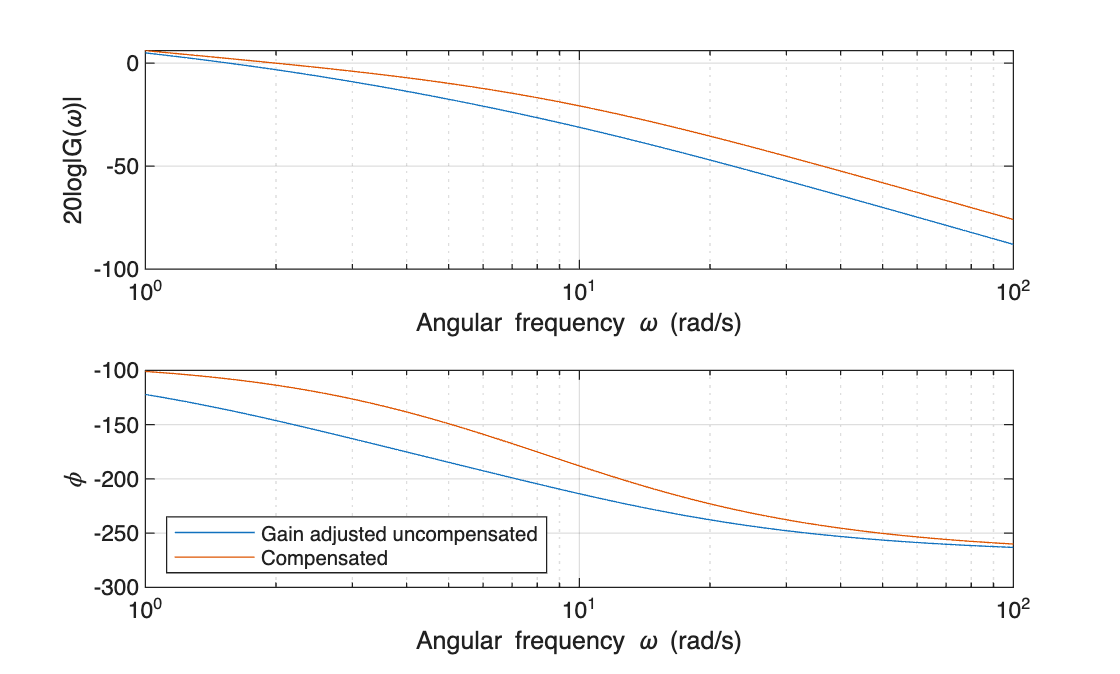



figure(3)
title('Loop transfer functions Bode diagrams')
[mag2,phase2] = bode(Gt,omega);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);
subplot(2,1,1)
semilogx(omega,20*log10(mag1))
hold on
semilogx(omega,20*log10(mag2))
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('20log|G(\omega)|')
subplot(2,1,2)
semilogx(omega,phase1)
hold on
semilogx(omega,phase2)
hold off
grid on
xlabel('Angular frequency \omega (rad/s)'),ylabel('\phi')
legend('Gain adjusted uncompensated','Compensated','Location','southwest')


[Gm,Pm,omegcp,omegcg] = margin(Gt);
dBGm = 20*log10(Gm);
disp(['Compensated system phase margin (degrees): ',num2str(Pm)])

Compensated system phase margin (degrees): 66.2905


disp(['Compensated system cross over angular frequency (rad/s): ',...
num2str(omegcg)])

Compensated system cross over angular frequency (rad/s): 2.0009


disp(['Compensated system gain margin (dB): ',num2str(dBGm)])

Compensated system gain margin (dB): 18.2018


disp(['Compensated system gain margin cross over angular frequency (rad/s): '...
,num2str(omegcp)])

Compensated system gain margin cross over angular frequency (rad/s): 8.6935


Then For the first $\omega_{\max } =2\ldotp 7$, the PM didn't meet the requiement, we do another iteration, increase the $\omega_{\max } =3$, The PM meet the requiements

disp("Compensated system transfer function"+...
"(i.e., the closed loop transfer function):")

Compensated system transfer function(i.e., the closed loop transfer function):


T2 = feedback(Gt,1)


T2 =
 
               160.91 (s+1.795)
  ------------------------------------------
  (s+12.49) (s+1.612) (s^2 + 5.117s + 14.34)
 
Continuous-time zero/pole/gain model.


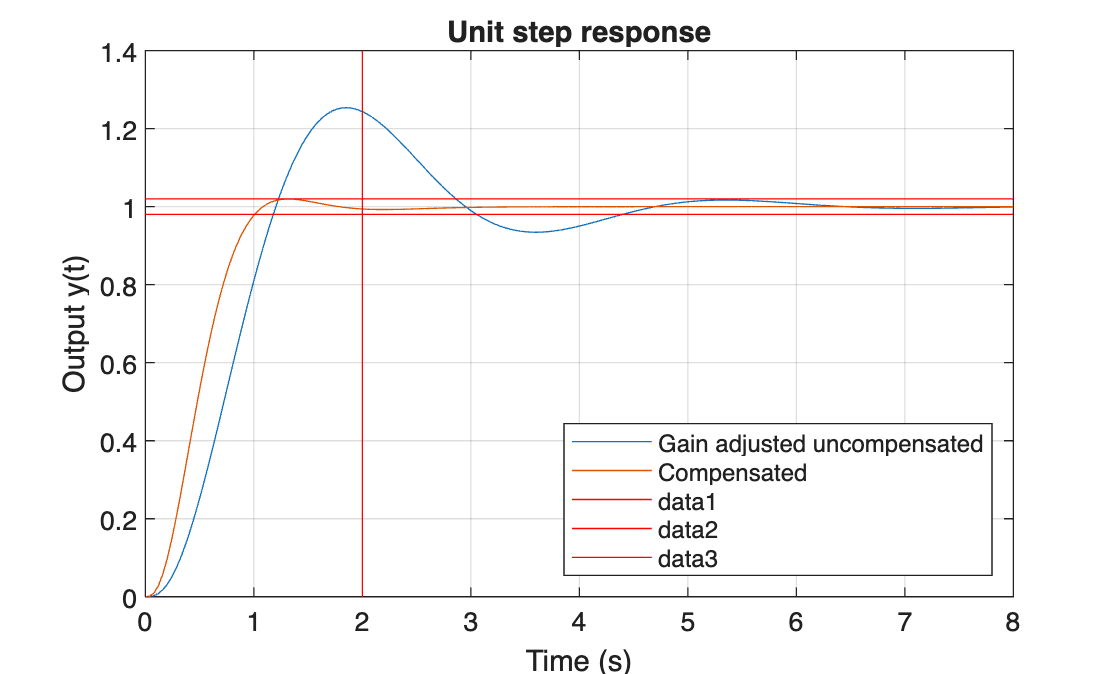

y2 = step(T2,tt);
figure(4)
plot(tt,y,tt,y2)
legend('Gain adjusted uncompensated','Compensated','location','southeast')
hold on
plot([tt(1), tt(end)],[1.02, 1.02],'r')
plot([tt(1), tt(end)],[0.98, 0.98],'r')
plot([2, 2],[0.0, 1.4],'r')
grid on
xlabel('Time (s)')
ylabel('Output y(t)')
title('Unit step response')
hold off